Initialize

x_gps = gps.UTM_easting;
y_gps = gps.UTM_northing;
time_gps = gps.Time;

Forward Velocity from GPS data

vel_gps = zeros(length(y_gps),1);
vel_gps(1) = 0;
for i = 2:length(y_gps)
    vel_gps(i) = sqrt((y_gps(i)-y_gps(i-1))^2+(x_gps(i)-x_gps(i-1))^2)/(time_gps(i)-time_gps(i-1));
end 

Plotting forward velocity from GPS data

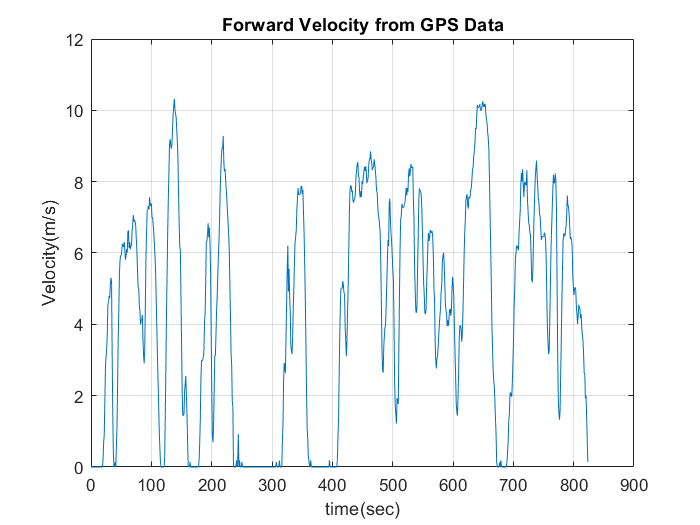

plot(time_gps - time_gps(1),vel_gps)
grid on
title("Forward Velocity from GPS Data")
xlabel('time(sec)')
ylabel('Velocity(m/s)')

Forward Velocity from accelerometer without correction

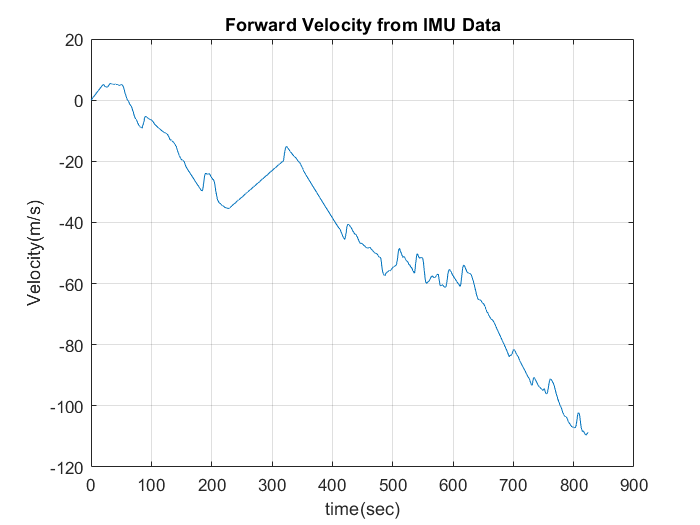

x_acc = imu_d.IMUlinear_accelerationy;
vel_imu = cumtrapz(time, x_acc);
plot(time - time(1),vel_imu)
grid on
title("Forward Velocity from IMU Data")
xlabel('time(sec)')
ylabel('Velocity(m/s)')

Forward Velocity from accelerometer without correction

hold off

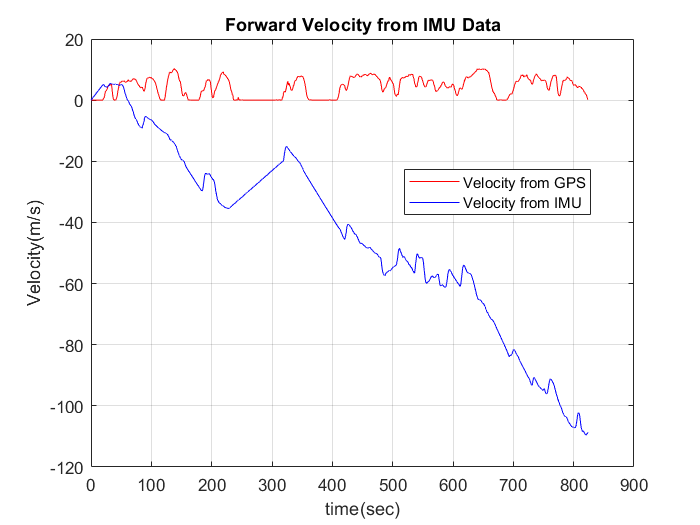

x_acc = imu_d.IMUlinear_accelerationy;
plot(time_gps - time_gps(1),vel_gps,'r')
grid on
hold on
title("Forward Velocity from IMU Data")
xlabel('time(sec)')
ylabel('Velocity(m/s)')
vel_imu = cumtrapz(time, x_acc);
plot(time - time(1),vel_imu,'b')
legend("Velocity from GPS", "Velocity from IMU","Location","best")

hold off

Plotting forward acceleration

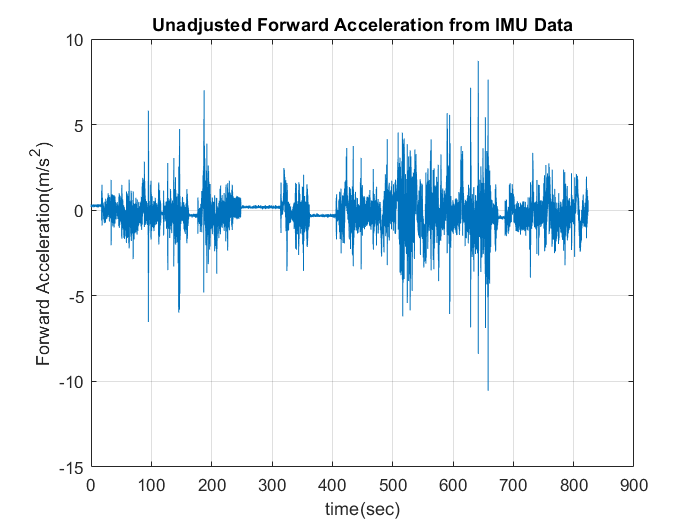

plot(time - time(1),x_acc)
title("Unadjusted Forward Acceleration from IMU Data")
xlabel('time(sec)')
grid on
ylabel('Forward Acceleration(m/s^2)')

Plotting forward acceleration

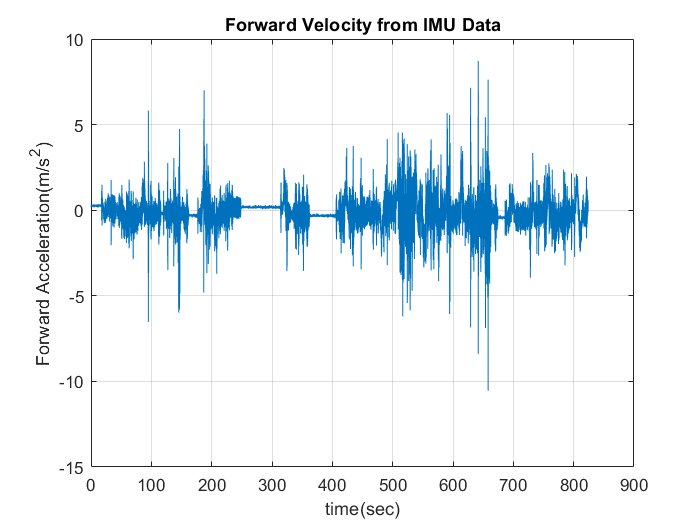

plot(time - time(1),x_acc)
title("Forward Velocity from IMU Data")
xlabel('time(sec)')
grid on
ylabel('Forward Acceleration(m/s^2)')

Segment Indices

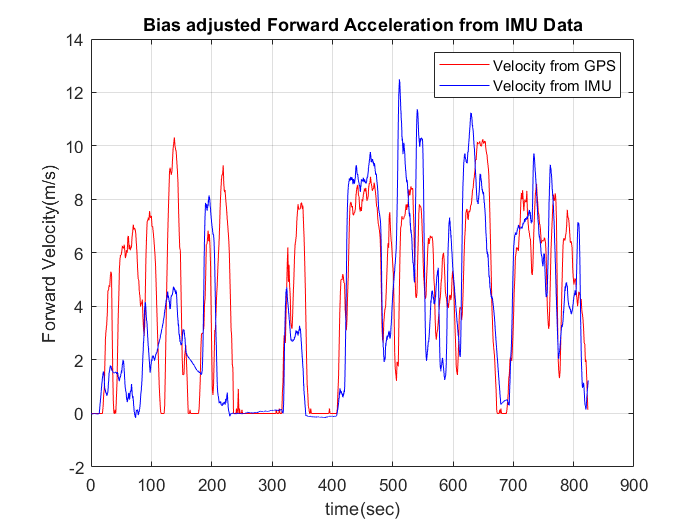

x_mod = x_acc;
norm = time - time(1);
seg = [0 13.7087 21.1048 38.4137 37.3104 50.9807 84.9495 97.9567 183.523 208.686 225.973... 
    319.491 331.473 347.304 335.224 356.06 407.285 419.916 424.893 487.025...
    512.011 445.178 479.77 470.09 496.406 617.239 644.779 669.264... 
    679.219 693.327 700.48 730.37 774.817 785.373 802.306 807.783 815.063 823.992...
    212.315 229.921];
offset_scaling = [1 0 1 1 1 1 1 1 1 1 1 0 1 1 0.1 1 1.2 -0.5 1.2 -0.4 0 -1 0 -1 ... 
     -1.5 1 0.3 0.3 1 -1.5 1.1 0 1.5 1 0.5 0 1.5 0 -0.6];
% last index 823.474
seg_ind = zeros(length(seg),1);
for j = 1: length(seg)
        seg_ind(j) = find(abs(norm - seg(j)) < 0.01);   
end
x_mod = x_acc;
c=0;
% x_mod(seg_ind(1):seg_ind(2)) = x_mod(seg_ind(1):seg_ind(2)) - mean(x_acc(1:669));
for i = 1: length(seg_ind)-1
    c = c+1;
    x_mod(seg_ind(i):seg_ind(i+1)) = x_mod(seg_ind(i):seg_ind(i+1)) - offset_scaling(i)*mean(x_acc(seg_ind(i):seg_ind(i+1)));
end
vel_mod = cumtrapz(time, x_mod);
plot(time_gps - time_gps(1),vel_gps,'r')
grid on
hold on
plot(time - time(1),vel_mod,'b')
legend("Velocity from GPS", "Velocity from IMU")
title("Bias adjusted Forward Acceleration from IMU Data")
xlabel('time(sec)')
grid on
ylabel('Forward Velocity(m/s)')
hold off

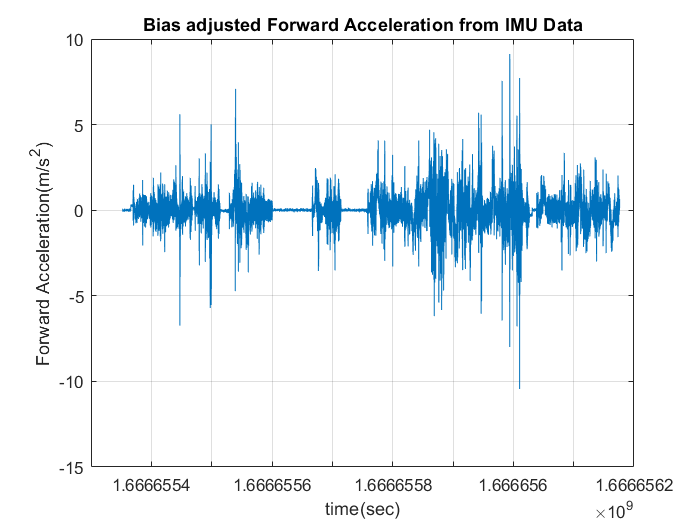

plot(time, x_mod)
title("Bias adjusted Forward Acceleration from IMU Data")
xlabel('time(sec)')
grid on
ylabel('Forward Acceleration(m/s^2)')